clc;
clear;
close all;

Method = "Gunshot";
if strcmp(Method,"Sweep Sine")
    SampleRate = 44100;				% Sample rate (Hz)
    samplesPerFrame = 1024; 				% Samples per frame
    durationPerRun = 3; 	% Duration per Run (s)
    outputLevel = -6;		% Excitation Level (dBFS)
    nbWarmUps = 0;			% Number of warm-up runs
    sweepRange = [10 22000]; % Sweep start/stop frequency (Hz)
    sweepDur = 1;			% Sweep Duration (s)
    
    Results = Sweep(SampleRate,samplesPerFrame,durationPerRun, ...
        outputLevel,nbWarmUps,sweepRange,sweepDur,'ImpulseResponse.wav');
else
    SamplesPerFrame = 1024; 
    fs = 44100; % Sampling frequency (Hz)
    duration = 1; % Duration of the sound (seconds)
    attack_time = 0.01; % Duration of the attack (seconds)
    decay_time = 0.05; % Duration of the decay (seconds)
    Results = Gunshot(fs,SamplesPerFrame,duration,attack_time, ...
        decay_time,'ImpulseResponse.wav');
end

Recording...
Computing results...


T_func = iosr.acoustics.irStats('ImpulseResponse.wav')

T_func = 2.2972

Read Response and create time vector

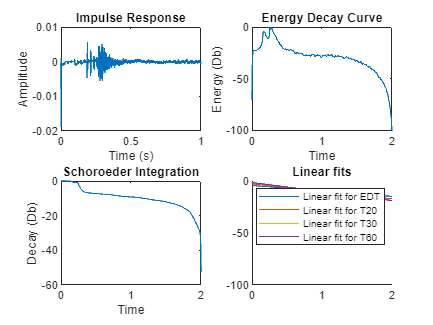

[impulseResponse_wav, fs_wav] = audioread('ImpulseResponse.wav');
impulseResponse = mean(impulseResponse_wav, 2);
sound_duration = length(impulseResponse)/fs_wav;
t_wav = 0:1/fs_wav:sound_duration;
vectorTiempo = t_wav(1:end-1);
truncatedResponse = impulseResponse(1:end);
hsq = impulseResponse.^2;

% [~,Startidx] = max(irdata_232024.ImpulseResponse.Amplitude(1:3000));
% truncatedResponse = irdata_232024.ImpulseResponse.Amplitude(Startidx:Startidx+999);
% fs = irdata_232024.SampleRate;
% responseLength = length(truncatedResponse);
% vectorTiempo = ones(responseLength,1);
% for i = 1:responseLength
%     vectorTiempo(i) = i/fs;
% end
subplot(2,2,1)
plot(vectorTiempo,truncatedResponse)
title('Impulse Response')
ylabel('Amplitude')
xlabel('Time (s)')

Energy decay curve

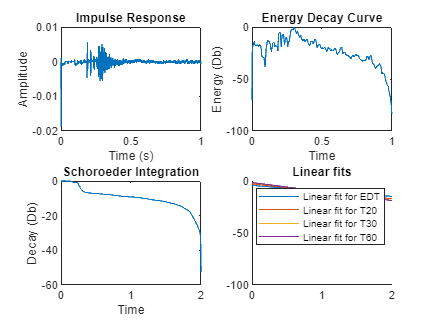

IRf = ACweight_time_filter(3,truncatedResponse);
IRfh_temp = abs(hilbert(IRf));
alpha = 0.5; % Shape parameter (0 = rectangular window, 1 = Hann window)
N = length(IRfh_temp); % Length of the signal
taper_length = round(alpha * N); % Length of the taper region
end_window = 0.5+(0.5*(cos(pi * (0:taper_length-1) / taper_length))); % Raised cosine window
window = [ones(1, N - taper_length), end_window]; % Combine rectangular and tapered regions
IRfh = IRfh_temp.*window';
IRfhn = (IRfh-min(IRfh))./(max(IRfh)-min(IRfh));
windowWidth = 701; 
kernel = ones(1,windowWidth) / windowWidth;
IRfhnf = filter(kernel,1, IRfhn);
E_t = 20*log10(IRfhnf/max(IRfhnf)); 
%plot(vectorTiempo,truncatedResponse)
% hold on
% plot(vectorTiempo,IRf)
% plot(vectorTiempo,IRfh)
% plot(vectorTiempo,IRfhn)
% plot(vectorTiempo,IRfhnf)
% hold off
%legend('Impulse Response','IR filtered','IRf enveope','IRfh normalized','IRfhn filtered')
subplot(2,2,2)
plot(vectorTiempo,E_t)
title('Energy Decay Curve')
xlabel('Time')
ylabel('Energy (Db)')

Schroeder Integration

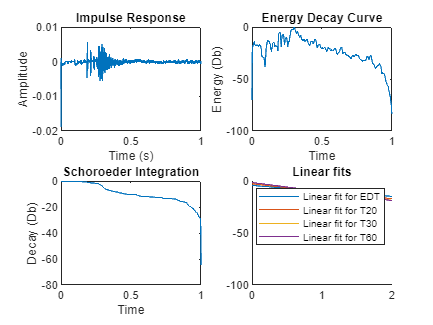

schroeder_cumsum = cumsum(flipud(truncatedResponse.^2));
schroeder_normalized = schroeder_cumsum / max(schroeder_cumsum);
L = flipud(10*log10(schroeder_normalized));
subplot(2,2,3)
plot(vectorTiempo,L)
title('Schoroeder Integration')
xlabel('Time')
ylabel('Decay (Db)')

Linear fit for Schroeder Integration

[~, Minus5DbIdx] = min(abs(L+5));
[~, Minus15DbIdx] = min(abs(L+15));
[~, Minus25DbIdx] = min(abs(L+25));
[~, Minus35DbIdx] = min(abs(L+35));
[~, Minus65DbIdx] = min(abs(L+65));

X_EDT = vectorTiempo(Minus5DbIdx:Minus15DbIdx);
X_T20 = vectorTiempo(Minus5DbIdx:Minus25DbIdx);
X_T30 = vectorTiempo(Minus5DbIdx:Minus35DbIdx);
X_T60 = vectorTiempo(Minus5DbIdx:Minus65DbIdx);

L_EDT = L(Minus5DbIdx:Minus15DbIdx); 
L_T20 = L(Minus5DbIdx:Minus25DbIdx); 
L_T30 = L(Minus5DbIdx:Minus35DbIdx); 
L_T60 = L(Minus5DbIdx:Minus65DbIdx); 

P_EDT = polyfit(X_EDT,L_EDT,1);
P_T20 = polyfit(X_T20,L_T20,1);
P_T30 = polyfit(X_T30,L_T30,1);
P_T60 = polyfit(X_T60,L_T60,1);

LF_EDT = P_EDT(1)*vectorTiempo+P_EDT(2);
LF_T20 = P_T20(1)*vectorTiempo+P_T20(2);
LF_T30 = P_T30(1)*vectorTiempo+P_T30(2);
LF_T60 = P_T60(1)*vectorTiempo+P_T60(2);

Linear fit for Energy Decay Curve

Plotting

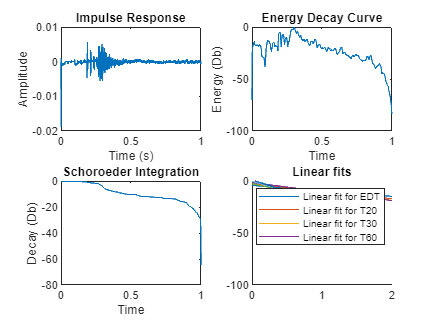

% plot(vectorTiempo,E_t)
% hold on
% plot(vectorTiempo,L)
% plot(vectorTiempo,LF_EDT)
% plot(vectorTiempo,LF_T20)
% plot(vectorTiempo,LF_T30)
% plot(vectorTiempo,LF_T60)
% ylim([-100, 0])
% legend('Energy decay curve','Schoroeder integration', ...
%     'Linear fit for EDT','Linear fit for T20','Linear fit for T30', ...
%     'Linear fit for T60')
% hold off

subplot(2,2,4)
hold on
plot(vectorTiempo,LF_EDT)
plot(vectorTiempo,LF_T20)
plot(vectorTiempo,LF_T30)
plot(vectorTiempo,LF_T60)
ylim([-100, 0])
legend('Linear fit for EDT','Linear fit for T20','Linear fit for T30', ...
     'Linear fit for T60')
title('Linear fits')
hold off

Acoustic parameters calculation

[~, EDT_Idx] = min(abs(LF_EDT+60));
T60delEDT = vectorTiempo(EDT_Idx)

T60delEDT = 1

[~, T20_Idx] = min(abs(LF_T20+60));
T60delT20 = vectorTiempo(T20_Idx)

T60delT20 = 1

[~, T30_Idx] = min(abs(LF_T30+60));
T60delT30 = vectorTiempo(T30_Idx)

T60delT30 = 1

[~, T60_Idx] = min(abs(LF_T60+60));
T60delT60 = vectorTiempo(T60_Idx)

T60delT60 = 1

V = 6*4*3.5; %Volume of the room
S = 120; %Surface of the room
Abso = 0.161*V/S*T60delEDT;

A = 60/T60delEDT; %Decay rate from reverberation time
%hsq = A*exp(-13.8*vectorTiempo/T60delEDT); %Distribution in time of impulse response squared, assuming exponential decay

[~, ClarIdx] = min(abs(vectorTiempo-0.8));
t_0a80 = vectorTiempo(1:ClarIdx); 
t_80aEnd = vectorTiempo(ClarIdx+1:end); %Time intervals for integration
hsq_0a80 = hsq(1:ClarIdx); 
hsq_80aEnd = hsq(ClarIdx+1:end); %Amplitude intervals for integration

C = 10*log10(trapz(t_0a80,hsq_0a80)/trapz(t_80aEnd,hsq_80aEnd)); %Clarity calculation
G = 10*log10(T60delEDT/V)+45; %Expected sound strength